# Find the NASDAQ 100 Winner and Loser

We will read the stock prices of the NASDAQ 100 to find the 20204 Q1's winner, loser, most volatile, and least volatile stocks.

## Getting the right add-on

First, we have to add the hist_stock_data add-on to MATLAB.  We do this using the "Add-Ons" button.

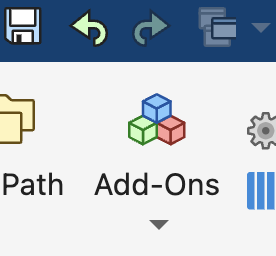

## Next we use `hist_stock_data`

Use hist_stock_data to get the stock pricess for the NASDAQ 100 for the first quarter of 2024.  The first quarter runs from January 1, 2024 to March 31, 2024.

The stock tickers for the NASDAQ 100 are stored in the file NASDAQ100.txt provided with the assignment.  To save time on multiple runs, we only load the data if we haven't already read it in this session.

if ~exist('stocks','var')
    stocks = hist_stock_data('01012024', '31032024', 'NASDAQ100.txt');
end
stocks(1,1:10)

Index in position 1 exceeds array bounds.

hist_stock_data returns 101 structs(one company has two classes of stock.)  Now we can analyze the data in these structs.

### Percentages

We will use the percent difference between beginning and end to find the winning and losing stock.  The equation looks like this:


$$\textrm{percentChange}=\frac{\left(\textrm{March30Price}-\textrm{Jan1Price}\right)}{\textrm{Jan1Price}}\;x\;100$$


## Find the winner and loser

We find the winner by finding the percent differences in the stock prices at the beginning and end of the quarter.  That is, index 1 and index `end` of `AdjClose`.

percentChange = zeros(1,numel(stocks));
stockStdDev = zeros(1,numel(stocks));
for ii = 1:numel(stocks)
    adjClose = stocks(ii).AdjClose;
    percentChange(ii) = (adjClose(end) - adjClose(1)) ./ adjClose(1) .* 100;
    stockStdDev(ii) = std(adjClose);
end

[winper, windex] = max(percentChange)
[loseper, lindex] = min(percentChange)
[volstock, vindex] = max(stockStdDev)
[quistock, qindex] = min(stockStdDev)

Now that we've calculated the percentChange we can print the winner and loser names

disp(["Winner:" stocks(windex).Ticker "Percent Growth" percentChange(windex)])
disp(["Loser:" stocks(lindex).Ticker "Percent Growth" percentChange(lindex)])

## Measuring Volitility with Standard Deviation

Now we will find the most vlatile and least volatile stocks by finding the standard deviation of their closing prices

disp(["Craziest Stock" stocks(vindex).Ticker "STDDEV" stockStdDev(vindex)])
disp(["Quietest Stock" stocks(qindex).Ticker "STDDEV" stockStdDev(qindex)])